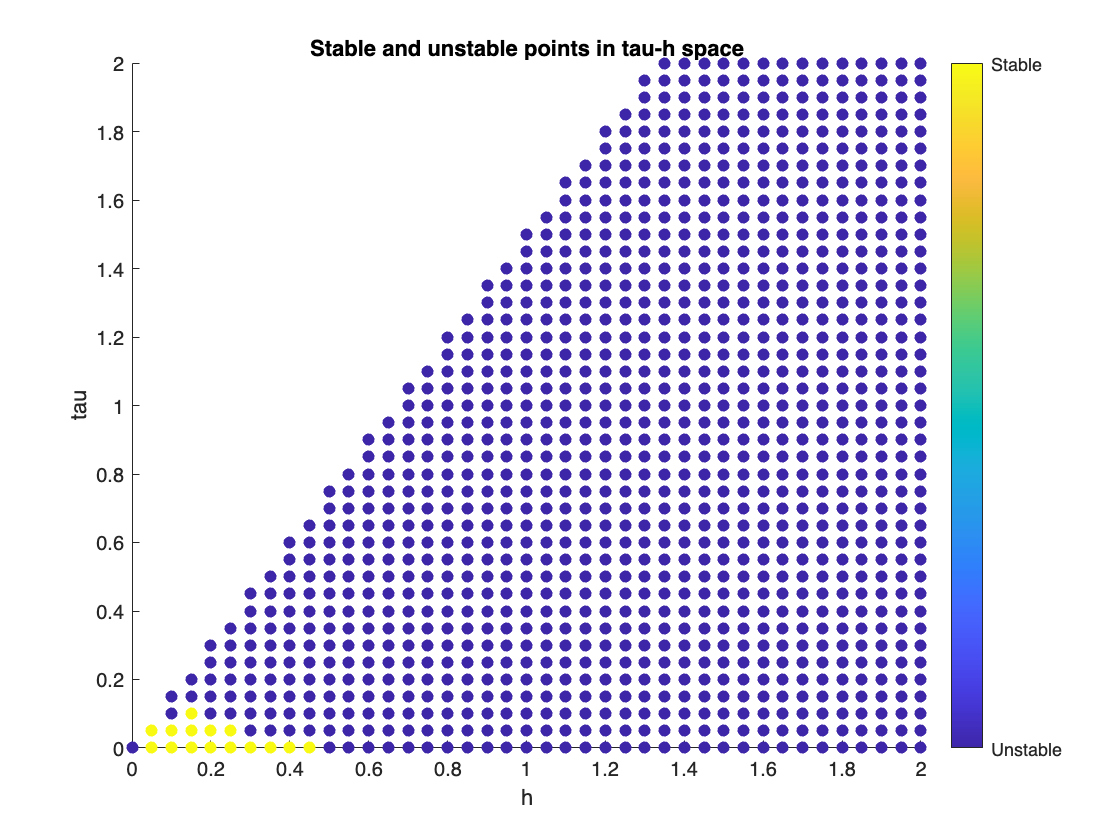

%Question 3-1
a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];
p1 = [-1+2j, -1-2j];
K1 = place(A, B, p1);

% create grid of tau and h values
tau_values = 0:0.05:2;
h_values = 0:0.05:2;

% preallocate arrays for x, y, and color values
x = [];
y = [];
colors = [];

xh = [];
yh = [];
colorsh = [];

%0<= tau <=h
for i = 1:length(tau_values)
    h = h_values(i);
    tau_values_i = 0:0.05:h;
    for j = 1:length(tau_values_i)
        tau = tau_values_i(j);
        
        % compute closed-loop system matrix
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau)))/A * B;
        G1 = (expm(A*(h-tau)) - eye(size(A)))/A * B;
        Fe = [Fx, Fu; zeros(1,2) zeros(1)]; 
        Ge = [G1; 1];
        Ke1 = [K1 0];
        Acl1de1 = Fe - Ge * Ke1;

        % check stability of closed-loop system
        eigvals1 = eig(Acl1de1);

        if all(abs(eigvals1) < 1)
            % point is stable, add to x, y, and color arrays
            x = [x h];
            y = [y tau];
            colors = [colors 1]; 
        else
            % point is unstable, add to x, y, and color arrays
            x = [x h];
            y = [y tau];
            colors = [colors 0]; % use NaN for invisible
        end
    end
end

% %h<= tau <=1.5h

% create grid of tau and h values
tau_values = 0:0.05:2;
h_values = 0:0.05:2;
for i = 1:length(tau_values)
    h = h_values(i);
    tau_values_i = h:0.05:1.5*h;
    for j = 1:length(tau_values_i)
        tau = tau_values_i(j);
        
        % compute closed-loop system matrix
        Fxh = expm(A*h);
        Fuh = (expm(A*h) - expm(A*(2*h-tau)))/A * B;
        Gh = (expm(A*(2*h-tau)) - eye(size(A)))/A * B;
        F = [Fxh, Fuh, Gh; zeros(size(Fxh)),[0;1],zeros(2,1)]; 
        G = [zeros(size(Fxh(:,1))); 1; 0];
        Ke1 = [K1 0 0];
        Acl1de1h = F - G * Ke1;

        % check stability of closed-loop system
        eigvals1h = eig(Acl1de1h);

        if all(abs(eigvals1h) < 1)
            % point is stable, add to x, y, and color arrays
            xh = [xh h];
            yh = [yh tau];
            colorsh = [colorsh 1]; 
        else
            % point is unstable, add to x, y, and color arrays
            xh = [xh h];
            yh = [yh tau];
            colorsh = [colorsh 0]; % use NaN for invisible
        end
    end
end


% plot scatter
figure;
scatter(x, y, [], colors, 'filled');
hold on 
scatter(xh, yh, [], colorsh, 'filled');
xlim([0 2]);
ylim([0 2]);
xlabel('h');
ylabel('tau');
title('Stable and unstable points in tau-h space');
colorbar('Ticks', [0, 1], 'TickLabels', {'Unstable', 'Stable'});